# Vehicle Climate Control System

This example models a vehicle climate control system. This system uses a Stateflow® controller to manage heating, air conditioning, and blower functions. To see an example of how to integrate this system with a plant model, see [Vehicle Electrical and Climate Control Systems](https://www.mathworks.com/help/simulink/slref/vehicle-electrical-and-climate-control-systems.html).

Open the model `sldemo_auto_climatecontrol.slx`.

open_system("sldemo_auto_climatecontrol.slx")

## Climate Control System

You can specify two inputs to the system:

- The `UserSetpointInCelius` subsystem block represents the target temperature inside the vehicle.

- The `ExternalTemperatureInCelius` subsytem block represents the temperature outside the vehicle.

The system outputs the temperature reading from a sensor behind the head of the driver, which reflects the temperature that the driver experiences. After simulation, this reading appears in the Display block, `Thermometer Display`.

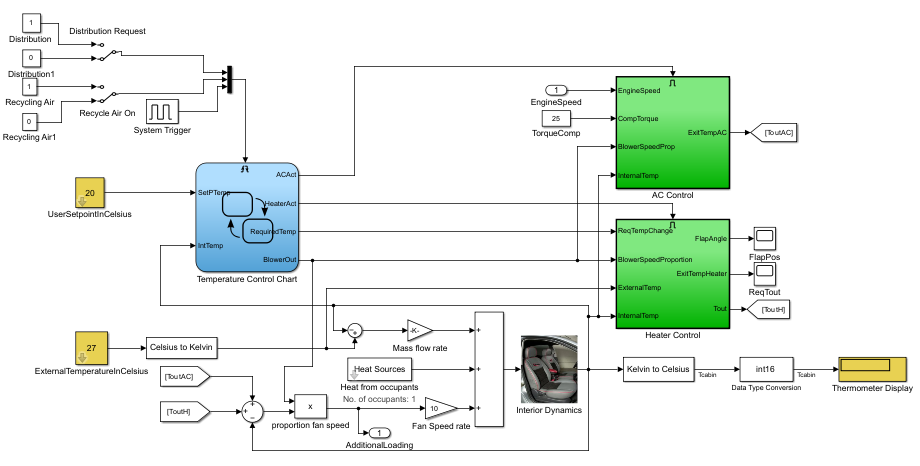

## Stateflow Controller

The `Temperature Control `chart manages supervisory control logic implementation. There are four different child states that run simultaneously to control different aspects of the climate inside the car.

- The `Heater_AC` state manages heating and cooling cycles.

- The `Blower` state controls fan speed.

- The `AirDist` state controls air distribution.

- The `Recyc_Air` state controls air recycling.

The `Heater_AC` state manages your primary temperature control cycles. The chart activates the heater when the setpoint exceeds room temperature by 0.5°C, running until it reaches the target range. Conversely, the AC engages when room temperature rises 0.5°C above setpoint. To prevent rapid cycling between heating and cooling, your system maintains a 0.5°C dead band around the target temperature.

In the `Blower` state adjusts fan speed based on the temperature differential. This proportional control ensures efficient temperature adjustment regardless of the initial difference. The system powers down when you reach within 0.5°C of your setpoint, optimizing energy usage while maintaining comfort.

The state `AirDist` responds to driver switch inputs for air blower output. 

When the driver activates defrost mode, the `Recyc_Air` state disables air recycling.

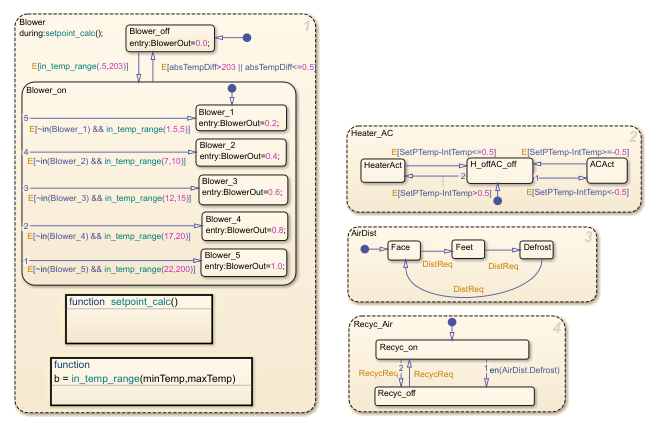

## Heater and Air Conditioner Models

The heater model is built from this equation for a heat exchanger:

where:

- *Ts* = constant (radiator wall temperature)

- *D* = 0.004m (channel diameter)

- *L* = 0.05m (radiator thickness)

- *N* = 30000 (Number of channels)

- *k* = 0.026 W/mK = constant (thermal conductivity of air)

- *Cp* = 1007 J/kgK = constant (specific heat of air)

- Laminar flow (hc = 3.66(k/D) = 23.8 W/m2K )

The model considers the effect of the heater flap. Similar to the blower operation, the heat flap output is proportional to the difference between the setpoint temperature and the current temperature. The greater the temperature difference, the more the heat flap opens and increases the heating effect.

The air conditioner (AC) system is one of the two places where the climate control model interfaces with the vehicle electrical system model. The compressor loads the vehicle engine when the AC system is active. The model implements this equation to determine the AC final temperature:

where:

- *y* = efficiency

- *m_dot* = mass flow rate

- *w* = speed of the engine

- *Tcomp* = compressor torque

- *h4*, *h1* = enthalpy

For the AC system, the model implements bang-bang control. The engine speed and compressor torque control the air temperature that exits the AC.

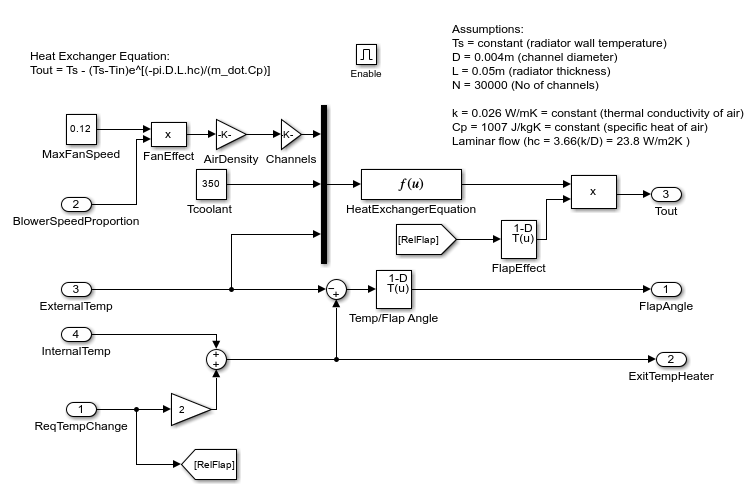

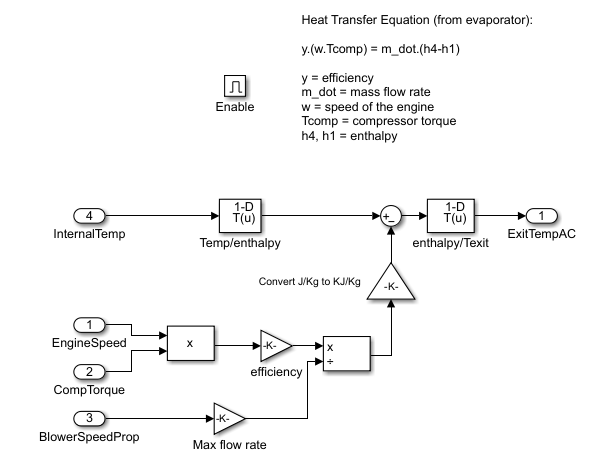

*Copyright 1990-2025 The MathWorks, Inc.*